# **N-body propagator**

**Objective:** to propagate the orbit of an asteroid taking into account the gravitational attractions of the solar system bodies.

**Initial conditions:** position and velocity of the asteroid

- Integration center: **Solar-System-Barycenter**

- Reference frame: **Ecliptic J2000**

The dynamics of the system is as follows:


$$\begin{cases}
\frac{d\mathbf{r}}{dt} &=& \mathbf{v} \\[0.5em]
\frac{d\mathbf{v}}{dt} &=& - \sum_{i=1}^{N}  \frac{GM_i \; \mathbf{r}_{i,o}}{\left|r_{i,o}\right|^3}
\end{cases}$$


where ${\textrm{GM}}_i$ is the gravitational parameter of the $i$-th body and the vector $\mathbf{r_{i,o}}$ is the position vector of the object we want to propagate w.r.t. the $i$-th body.

When preparing the propagator we have to keep in mind that during the propagation:

- the state vectors must be in the same reference frame;

- the units must be consistent.

## Initialization

clc, clear all, close all

% Load kernels
cspice_furnsh('sgn_nbody_propagator.tm');

% Define list of celestial bodies:
labels = {'Sun';
          'Mercury';
          'Venus';
          'Earth';
          'Moon';
          'Mars Barycenter';
          'Jupiter Barycenter';
          'Saturn Barycenter';
          'Uranus Barycenter';
          'Neptune Barycenter';
          'Pluto Barycenter'};

% Initialize propagation data
bodies = nbody_init(labels);

% select integration frame string (SPICE naming convention)
frame = 'ECLIPJ2000';

## Initial state

We now need to obtain the initial condition for the asteroid. We can do this using the database available through [NASA Horizons](https://ssd.jpl.nasa.gov/horizons.cgi#top).

% Define initial epoch string
asteroid_label = '65803 Didymos';
ref_epoch_str = '2021-Sep-29 00:00:00.0000 TDB';

et0 = cspice_str2et(ref_epoch_str);
x0 = [-2.898195468183491E+08; -1.793581822536078E+08;  1.337682542102944E+07;    % Position
       8.075315120230030E+00; -1.322285135735789E+01; -6.878649448008112E-01];   % Velocity

## Perform integration

final_epoch_str = '2025-Sep-29 00:00:00.0000 TDB';
etf = cspice_str2et(final_epoch_str);

options = odeset('reltol', 1e-12, 'abstol', 1e-12);
[tt, xx] = ode113(@(t,x) nbody_rhs(t,x,bodies,frame), [et0 etf], x0, options);

## Plots and analysis

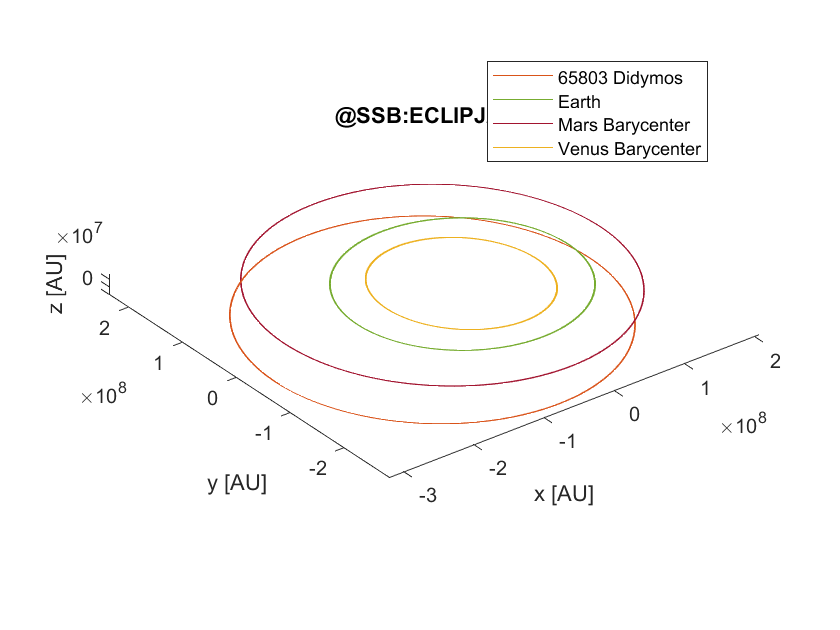

figure(1)
plot3(xx(:,1), xx(:,2), xx(:,3),'color','#D95319');
xlabel('x [AU]')
ylabel('y [AU]')
zlabel('z [AU]')
title (['@SSB:',frame])
axis equal
hold on

others = {'Earth', 'Mars Barycenter', 'Venus Barycenter'};
planet_colors = {'#77AC30','#A2142F','#EDB120'};
for i = 1:length(others)
    rr_planet = zeros(3, length(tt));
    for j = 1:length(tt)
        rr_planet(:,j) = cspice_spkpos(others{i},tt(j),frame,'NONE','SSB');
    end
    plot3(rr_planet(1,:), rr_planet(2,:), rr_planet(3,:),'color',planet_colors{i});
end
legend([asteroid_label,others],'Location','best');

### Earth distance

By looking at the Didymos orbit in the previous plot, we can observe that it is crossing the one of the Earth in at least two points. Therefore, we can compute the relative distance between the asteroid and the Earth and identify if there is an actual **close approach**.

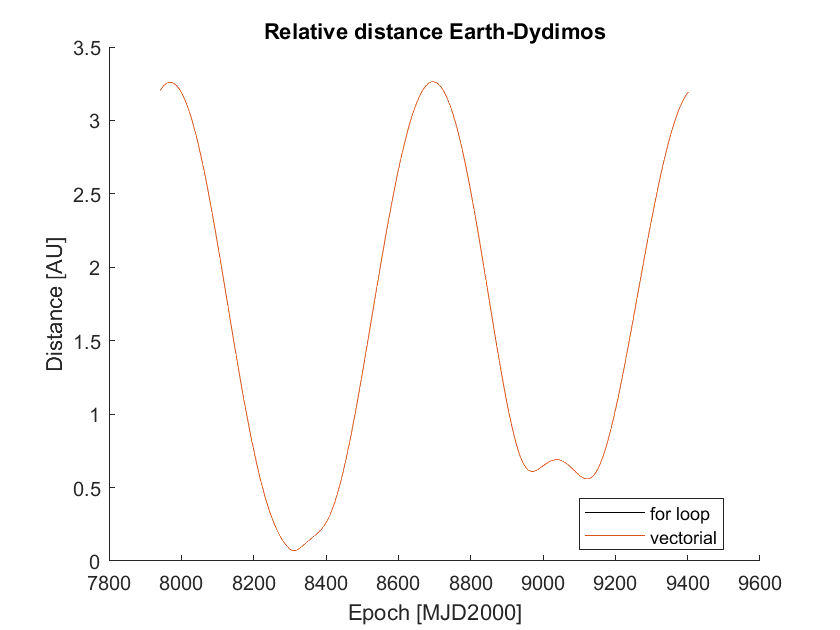

% Initialize distance vectors
dist = zeros(1,length(tt));

% A) We can do this by looping
for j = 1:length(tt)
    rr_earth_obj = xx(j,1:3)' ...
                   - cspice_spkpos('Earth',tt(j),frame,'NONE','SSB');

    dist(j) = cspice_convrt(norm(rr_earth_obj),'km','au');
end

% B) or we can do it in pure vectorial form, by exploiting the norm definition
rr_earth_obj = xx(:,1:3)' - cspice_spkpos('Earth',tt',frame,'NONE','SSB');
dist_km = sqrt(sum(rr_earth_obj.^2,1));
dist_AU = cspice_convrt(dist_km,'km','au');

figure(2)
hold on
plot(tt/cspice_spd(), dist,'k')
plot(tt/cspice_spd(), dist_AU)
title('Relative distance Earth-Dydimos')
xlabel('Epoch [MJD2000]')
ylabel('Distance [AU]')
legend({'for loop','vectorial'},'Location','best')

We can check on the Horizon's Small Bodies Database Lookup if our computation is close enough to the actual results. We can do this by opening the page on the NASA Small-Body Database Lookup: [65803 Didymos](https://ssd.jpl.nasa.gov/tools/sbdb_lookup.html#/?sstr=didymos)

% We take the two points for which the distance is smaller and compute the
% average value
et_CA = (8311.62+8312.26)/2*cspice_spd();
CA_epoch = cspice_et2utc(et_CA,'C', 1e-3);
fprintf('Close approach epoch [UTC]: %s', CA_epoch);

Close approach epoch [UTC]: 2022 OCT 04 10:32:27

Clear SPICE kernel pool

cspice_kclear();